PapayaHyperspectral

Source's Github: [https://github.com/cogsys-tuebingen/deephs_fruit](https://github.com/cogsys-tuebingen/deephs_fruit) 

Homepage: [https://paperswithcode.com/dataset/deephs-fruit-v2](https://paperswithcode.com/dataset/deephs-fruit-v2)

Downloads: [https://cogsys.cs.uni-tuebingen.de/webprojects/DeepHS-Fruit-2023-Datasets/](https://cogsys.cs.uni-tuebingen.de/webprojects/DeepHS-Fruit-2023-Datasets/) 

% clear

**Step 1: **Load One Hyperspectral Papaya to see if it looks right

hyperspectral_img = load('/Users/maycaj/Documents/Hyperspectral-Imaging/Papaya/matlab/hardness/hard/560.mat')

hyperspectral_img = struct with fields:
    hyperspectral_image: [520×234×224 single]
         headerfilepath: '/Users/maycaj/Documents/Hyperspectral-Imaging/Papaya/VIS/day_m4_02/papaya_day_m4_02_12_front.hdr'
             wavelength: [400 402.6906 405.3812 408.0717 410.7623 413.4529 416.1435 418.8341 421.5247 424.2152 426.9058 429.5964 432.2870 434.9776 437.6682 440.3587 443.0493 445.7399 448.4305 451.1211 453.8117 456.5022 459.1928 461.8834 … ] (1×224 double)


hyperspectral_cube = hypercube(hyperspectral_img.hyperspectral_image,hyperspectral_img.headerfilepath,hyperspectral_img.wavelength)

hyperspectral_cube =   hypercube with properties:

      DataCube: [520×234×224 single]
    Wavelength: [224×1 double]
      Metadata: [1×1 struct]


disp('Dimensions:')

Dimensions:


disp((size(hyperspectral_img.hyperspectral_image)))

   520   234   224



% hyperspectralViewer(hyperspectral_cube)

% Assuming ExtractCube is your hyperspectral data
[hyperspectral_cube, coeff, var] = hyperpca(hyperspectral_cube, 6);

% Display the percentage of variance explained by each principal component
disp('Percentage of Variance Explained by Each Principal Component:');

Percentage of Variance Explained by Each Principal Component:


disp(var);

   98.1792
    1.1766
    0.2416
    0.1330
    0.0602
    0.0263




resizedCube = imresize3(hyperspectral_cube, [64,64,64]);
disp('Size of resized Cube:')

Size of resized Cube:


disp(size(resizedCube))

    64    64    64



**Step 2: **Find the dimensions of each of the Datacubes and the Variance explained by each PCA variable

folderPath = '/Users/maycaj/Documents/Hyperspectral-Imaging/Papaya/matlab/hardness/soft/';

% Get information about the files in the folder
files = dir(fullfile(folderPath, '*.mat'));

var1 = [];
var2 = [];
var3 = [];

% Iterate over each file
for i = 1:numel(files)

    % Get the current file name
    currentFileName = files(i).name;
    % disp(['Processing file: ' currentFileName]);
    
    % Make the currentFilePath and load the file
    currentFilePath = [folderPath,currentFileName];
    % disp(['Current Filepath: ' currentFilePath]);
    hyperspectral_img = load(currentFilePath);
    % disp((size(hyperspectral_img.hyperspectral_image)))
    
    % Extract hyperspectral cube
    hyperspectral_cube = hypercube(hyperspectral_img.hyperspectral_image,hyperspectral_img.headerfilepath,hyperspectral_img.wavelength);
    [hyperspectral_cube, coeff, var] = hyperpca(hyperspectral_cube, 6);
    % disp('Percentage of Variance Explained by Each Principal Component:');
    % disp(var);

    var1 = [var1, var(1)];
    var2 = [var2, var(2)];
    var3 = [var3, var(3)];
end
disp('Average variance explained by first principal component:')

Average variance explained by first principal component:


disp(mean(var1))

   97.9199



disp('Average variance explained by second principal component:')

Average variance explained by second principal component:


disp(mean(var2))

    1.4225



disp('Average variance explained by third principal component:')

Average variance explained by third principal component:


disp(mean(var3))

    0.2480



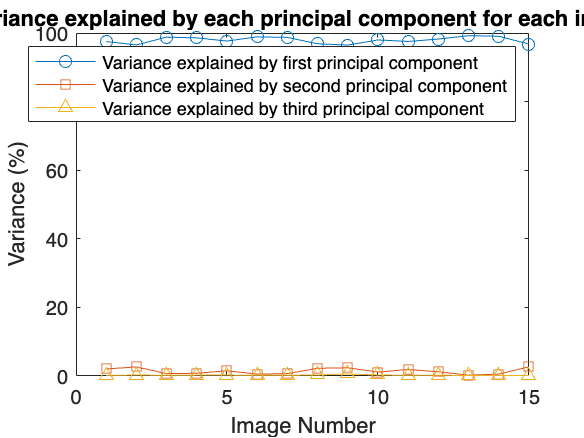


% Plot the three lists as series
x = 1:15;
figure;
plot(x, var1, 'o-', 'DisplayName', 'Variance explained by first principal component');
hold on;
plot(x, var2, 's-', 'DisplayName', 'Variance explained by second principal component');
plot(x, var3, '^-', 'DisplayName', 'Variance explained by third principal component');

% Add labels and legend
xlabel('Image Number');
ylabel('Variance (%)');
title('Variance explained by each principal component for each image');
legend('show');

% Hold off to stop overlaying plots
hold off;


% largest dimension = 406,213,224

Can start code here if only need to load data and train model:

**Step 3: **Make and ImageDatastore object that holds data to train

imds = imageDatastore('/Users/maycaj/Documents/Hyperspectral-Imaging/Papaya/matlab/hardness/', 'IncludeSubfolders',true, 'FileExtensions','.mat','LabelSource','foldernames')

imds =   ImageDatastore with properties:

                       Files: {
                              ' .../Documents/Hyperspectral-Imaging/Papaya/matlab/hardness/hard/553.mat';
                              ' .../Documents/Hyperspectral-Imaging/Papaya/matlab/hardness/hard/555.mat';
                              ' .../Documents/Hyperspectral-Imaging/Papaya/matlab/hardness/hard/557.mat'
                               ... and 39 more
                              }
                     Folders: {
                              '/Users/maycaj/Documents/Hyperspectral-Imaging/Papaya/matlab/hardness'
                              }
                      Labels: [hard; hard; hard ... and 39 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                    

imds.ReadFcn = @ExtractCubeCam;

**Step 4**: Open Deep Network Designer

deepNetworkDesigner